P_0 = 3;
x =  10:100:10000;
t = 10;

Air

f = 125;
omega = 2*pi*f; %angular frequency {rad/s}
rho_0 = 1.21;% density of the  fluid {kg/m^3}
c = 343; % speed of sound {m/s^2}

k = omega./c; % wave number

eta = 1.85e-5; % shear viscosity coefficient {Pa*s}
gamma = 1.402; % heat capacity ratio {1}
kappa = 0.0263; % thermal conductivity {W/m*K}
c_p = 1.01e3; %specific heat {J/Kg*K}
Pr = eta*c_p/kappa

Pr = 0.7105


% absorption coefficient
alpha_c_air = omega.^2./2./rho_0./c.^3.*(4/3.*eta + (gamma - 1).*kappa./c_p)

alpha_c_air = 2.2193e-07


% complex pressure
p_air = abs(P_0.*exp(-alpha_c_air.*x).*exp(1i.*(omega.*t - k.*x)))

p_air =     3.0000    2.9999    2.9999    2.9998    2.9997    2.9997    2.9996    2.9995    2.9995    2.9994    2.9993    2.9993    2.9992    2.9991    2.9991    2.9990    2.9989    2.9989    2.9988    2.9987    2.9987    2.9986    2.9985    2.9985    2.9984    2.9983    2.9983    2.9982    2.9981    2.9981    2.9980    2.9979    2.9979    2.9978    2.9977    2.9977    2.9976    2.9975    2.9975    2.9974    2.9973    2.9973    2.9972    2.9971    2.9971    2.9970    2.9969    2.9969    2.9968    2.9967


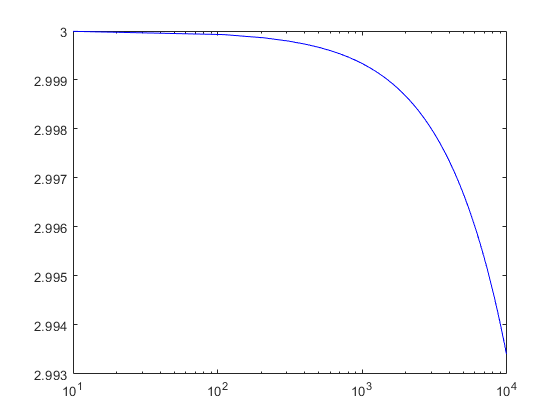


semilogx(x,p_air, 'b-')


% % viscosity term
% alpha_c_air_viscosity = omega.^2./2./rho_0./c.^3.*(4/3.*eta)
% 
% % conduction term
% alpha_c_air_conduction = alpha_c_air - alpha_c_air_viscosity;
% 
% figure
% semilogx(f,alpha_c_air_viscosity./alpha_c_air, 'b-')
% hold on
% semilogx(f,alpha_c_air_conduction./alpha_c_air, 'r-')
% legend('viscosity', 'conduction')

Water

f = 20:100:20000;
omega = 2*pi*f; %angular frequency {rad/s}
rho_0 = 998;% density of the  fluid {kg/m^3}
c = 1481; % speed of sound {m/s^2}

k = omega./c; % wave number

eta = 1.0e-3; % shear viscosity coefficient {Pa*s}
gamma = 1.004; % heat capacity ratio {1}
kappa = 0.603; % thermal conductivity {W/m*K}
c_p = 4.19e3; %specific heat {J/Kg*K}
Pr = eta*c_p/kappa

Pr = 6.9486


% absorption coefficient
alpha_c_water = omega.^2./2./rho_0./c.^3.*(4/3.*eta + (gamma - 1).*kappa./c_p)

alpha_c_water = 	1.0e+-5 *

    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0014    0.0016    0.0019    0.0021    0.0024    0.0027    0.0030    0.0033    0.0037    0.0040    0.0044    0.0048    0.0052    0.0056    0.0060    0.0065    0.0069    0.0074    0.0079    0.0084    0.0090    0.0095    0.0101    0.0106    0.0112    0.0119    0.0125    0.0131    0.0138    0.0145    0.0152    0.0159    0.0166    0.0173    0.0181    0.0189    0.0197



% complex pressure
%p_water = abs(P_0.*exp(-alpha_c_water.*x).*exp(1i.*(omega.*t - k.*x)))

% viscosity part
alpha_c_water_viscosity = omega.^2./2./rho_0./c.^3.*(4/3.*eta)

alpha_c_water_viscosity = 	1.0e+-5 *

    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0014    0.0016    0.0019    0.0021    0.0024    0.0027    0.0030    0.0033    0.0036    0.0040    0.0044    0.0048    0.0052    0.0056    0.0060    0.0065    0.0069    0.0074    0.0079    0.0084    0.0089    0.0095    0.0101    0.0106    0.0112    0.0118    0.0125    0.0131    0.0138    0.0145    0.0152    0.0159    0.0166    0.0173    0.0181    0.0189    0.0197



% conduction term
alpha_c_water_conduction = alpha_c_water - alpha_c_water_viscosity;

figure
semilogx(f,alpha_c_water_viscosity./alpha_c_water, 'b-')
hold on
semilogx(f,alpha_c_water_conduction./alpha_c_water, 'r-')
legend('viscosity', 'conduction')


Plot

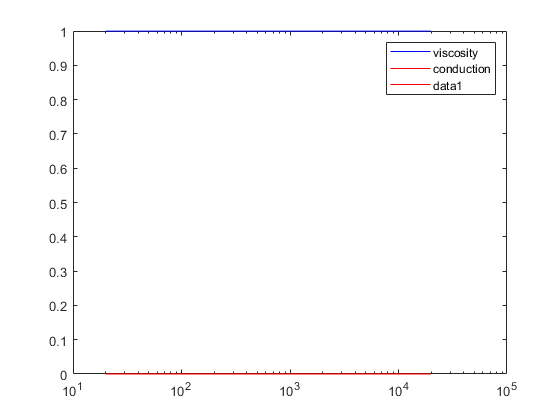




semilogx(f,alpha_c_water, 'r-')

complex pressure